ENTORNO

clear
clf

clear
close all
clf

T_M_U = transl(10,8,0.8)*trotz(pi/6); % Reference Frame Taula

v_ini= [0 0 0;1 0 0;1 1 0;0 1 0;0 0 1;1 0 1;1 1 1;0 1 1];
LDH = [2 0 0; 0 1 0; 0 0 0.1];
v = v_ini * LDH;
v = [v ones(size(v,1),1)];
v = (T_M_U * v')';
f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];

mesa = figure;
figure(mesa);
patch('Vertices',v(:,(1:3)),'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.5, 0.5 0.5], 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)
view(30,45)
axis equal

v_pata = v_ini * [0.1 0 0; 0 0.1 0; 0 0 0.7];
v_pata = [v_pata ones(size(v_pata,1),1)];

v_pata1 = (T_M_U * transl(0,0,-0.7) * v_pata')';
v_pata2 = (T_M_U * transl(1.9,0,-0.7) * v_pata')';
v_pata3 = (T_M_U * transl(1.9,0.9,-0.7) * v_pata')';
v_pata4 = (T_M_U * transl(0,0.9,-0.7) * v_pata')';

patch('Vertices',v_pata1(:,(1:3)),'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.5, 0.5 0.5], 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)
patch('Vertices',v_pata2(:,(1:3)),'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.5, 0.5 0.5], 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)
patch('Vertices',v_pata3(:,(1:3)),'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.5, 0.5 0.5], 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)
patch('Vertices',v_pata4(:,(1:3)),'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.5, 0.5 0.5], 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)


camlight('headlight')
material('dull')
view(30,45)
axis equal
hold on

trplot(T_M_U, 'frame', 'T', 'length', 1, 'arrow', 'color', 'b');

load("F_V_HumanBody.mat")

T_H_M = T_M_U * transl(0.42,0.5,0.3) * troty(pi/2) * trotz(-pi/2); % Reference Frame Humà wrt Taula
v_human = [Vh ones(size(Vh, 1),1)];
v_human = (T_H_M * v_human')';

patch('Vertices',v_human(:,(1:3)),'Faces',Fh,'FaceVertexCData',hsv(6),'FaceColor','y', 'FaceAlpha', 0.3, 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)
axis equal

trplot(T_H_M,'frame', 'H', 'length', 1, 'arrow', 'color', 'g');

skull = load("F_V_Skull.mat");
skull_vertices = skull.Vs;

T_I = troty(pi); % Reference Frame Imatge

T_CB_I = T_I * transl(0.041,0.026,0); % Reference Frame Capsa Contenidora wrt Imatge

xmaxs = max (skull_vertices(:, 1)); 
xmins = min(skull_vertices(:, 1)); 
ymaxs = max (skull_vertices (:, 2)); 
ymins = min(skull_vertices(:, 2));

xsize = abs(xmaxs - xmins)/2;
ysize = abs(ymaxs - ymins)/2;
zsize = max(skull_vertices( :,3));


%Capsa Contenidora Skull

x=0.150;
y=0.198;
z=0.156;
v= [0 0 0;x 0 0;x y 0;0 y 0;0 0 z;x 0 z;x y z;0 y z];

cube_vertices_cb = [v'; ones(1, length(v))];

cube_vertices_cb = (T_CB_I * cube_vertices_cb)';

cube_faces = [ 1 2 6 5; 2 3 7 6; 3 4 8 7; 4 1 5 8; 1 2 3 4; 5 6 7 8];

T_I_H = T_H_M * troty(pi) * transl(-(xsize+0.041),-(ysize+0.026),-(1.65+0.15)); % Reference Frame Imagen wrt Humà modificar para que quede como DICOM
T_F_I = T_I_H * transl(-0.015,0.016,0);
T_CB_I = T_I_H * troty(pi);

cube_vertices_cb = (T_CB_I * cube_vertices_cb')';
patch('Vertices',cube_vertices_cb(:, 1:3),'Faces',cube_faces,'FaceVertexCData',hsv(6),'FaceColor','g','FaceAlpha',0.3)


FIDUCIALS

F1_I = [0.06656 0.200 0.112 1]';
F2_I = [0.186 0.209 0.0658 1]';
F3_I = [0.122 0.062 0.0252 1]';
F1_U = T_F_I * F1_I;

[X,Y,Z] = sphere;

r2 = 0.005;

X3 = X * r2;
Y3 = Y * r2;
Z3 = Z * r2;

F1_U = T_I * F1_I;

surf(X3+F1_U(1,1),Y3+F1_U(2,1),Z3+F1_U(3,1),'FaceColor',[1 0 0])
axis equal

F2_U = T_F_I * F2_I;
surf(X3+F2_U(1,1),Y3+F2_U(2,1),Z3+F2_U(3,1),'FaceColor',[1 0 0])
axis equal

F3_U = T_F_I * F3_I;

surf(X3+F3_U(1,1),Y3+F3_U(2,1),Z3+F3_U(3,1),'FaceColor',[1 0 0])
axis equal

C_T = [0.130 0.097 0.049 1]'

C_T =     0.1300
    0.0970
    0.0490
    1.0000


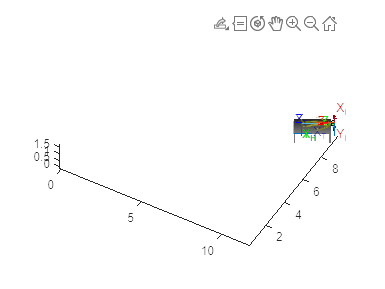


D_T = 0.033;

[X,Y,Z] = sphere;

r = D_T / 2;

X2 = X * r;
Y2 = Y * r;
Z2 = Z * r;

C_T_U = T_F_I * C_T;

surf(X2+C_T_U(1,1), Y2+C_T_U(2,1), Z2+C_T_U(3,1),'FaceColor',[1 0 0])
axis equal

trplot(T_I_H,'frame', 'I', 'length', 1, 'arrow', 'color', 'r')


mdl_puma560
T_F = p560.fkine(qz)

 

T_F = 
         1         0         0    0.4521
         0         1         0     -0.15
         0         0         1    0.4318
         0         0         0         1


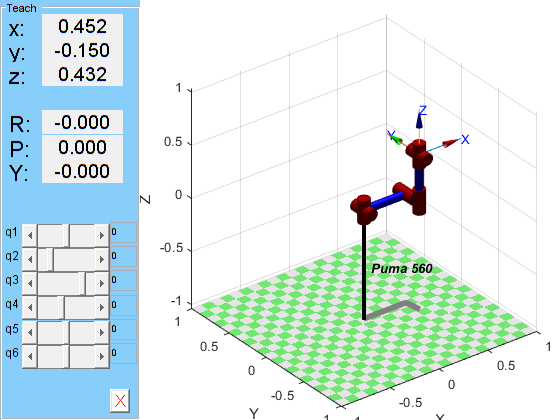


p560.plot(qz)
p560.teach


T_Rob = p560.base * transl(9,9,0);

Error using assert
LHS should be matrix with 3 rows

Error in  *  (line 357)
                    assert(numrows(a) == n-1, 'SMTB:RTBPose:badops', 'LHS should be matrix with %d rows', n-1);



[X,Y,Z] = sphere;

r = 0.1;

X2 = X * r + C_T(1);
Y2 = Y * r + C_T(2);
Z2 = Z * r + C_T(3);

% X2 = X * r + 0.3;
% Y2 = Y * r + 0.7;
% Z2 = Z * r + 0.5;

T_X = T_F.t(1);
T_Y = T_F.t(2);
T_Z = T_F.t(3)+0.3;

axis equal

% T_Z = [0 0 0.5];
% T_X = inv(T_Z) * [0 0 0];
% T_Y = cross(T_Z, T_X);

T_Tool_TC = transl(T_X,T_Y,T_Z);
T_A_Tool = transl(T_X, T_Y, T_Z - 0.3);

[S,SD,SDD] = tpoly(T_Z-0.3, T_Z-0.1, 10);

Qss = zeros(10,6)

% for i = 1:10
%     T_mov = T_A_Tool * transl(0,0,S(i));
%     Qss(i,:) = p560.ikine6s(T_mov)
% end

%for i = 1:10
Qss = p560.ikine6s(ctraj(T_A_Tool,T_Tool_TC,10))

p560.plot(Qss)

